%% AE 484 Live Script: Integrated Navigation with Zurich Urban MAV Dataset
% This live script implements a strapdown INS and integrated navigation
% solution (EKF and UKF) using the Zurich Urban Micro Aerial Vehicle (MAV)
% dataset. It also includes bonus comparisons of EKF vs UKF and discussion
% of loosely‐coupled vs tightly‐coupled GPS/INS integration.
%
% Sections:
%   1. Download & Setup Dataset
%   2. Load & Preprocess Data
%   3. Strapdown INS Mechanization (Pure INS)
%   4. Extended Kalman Filter (EKF) Implementation
%   5. Unscented Kalman Filter (UKF) Implementation
%   6. Run Filters & Collect Results
%   7. Plot Trajectories & Compare with Ground Truth
%   8. Plot Estimation Errors & ±3σ Bounds
%   9. Bonus: Loosely‐ vs Tightly‐Coupled Integration Discussion
%
% For best results, run this script section by section. Make sure you have
% MATLAB R2020b or later (for built‐in functions such as readmatrix). 
% No additional toolboxes are required—custom quaternion functions are
% provided at the end of this script.

%% 1. Download & Setup Dataset
% We use the Zurich Urban MAV dataset, which includes IMU (accelerometer + gyro), GPS,
% barometer, and ground truth trajectory. Data are time‐synchronized by PX4 autopilot clock.

dataFolder = 'AGZ';  % adjust path if different

%% 2. Load & Preprocess Data
% Load IMU (accelerometer + gyro), GPS, barometer, and ground truth logs.
% Convert timestamps from microseconds to seconds. Align all sensor data on a
% common time vector (we will use the IMU timestamps as the master clock).

% Paths to CSV files (adjust if your folder structure differs)
imuAccelFile  = fullfile(dataFolder,'Log Files','RawAccel.csv');
imuGyroFile   = fullfile(dataFolder,'Log Files','RawGyro.csv');
gpsFile       = fullfile(dataFolder,'Log Files','OnboardGPS.csv');
baroFile      = fullfile(dataFolder,'Log Files','BarometricPressure.csv');
gtFile        = fullfile(dataFolder,'Log Files','GroundTruthAGL.csv');

fprintf('Loading IMU accelerometer data...\n');

Loading IMU accelerometer data...


accelDataRaw = readmatrix(imuAccelFile);  
% Columns: time_us | ax | ay | az | (others ignored)
timeAccel_us = accelDataRaw(:,1);
accelData    = accelDataRaw(:,2:4);  % 3×N accelerometer in m/s^2
fprintf('Loading IMU gyro data...\n');

Loading IMU gyro data...


gyroDataRaw = readmatrix(imuGyroFile);  
% Columns: time_us | gx | gy | gz | (others ignored)
timeGyro_us = gyroDataRaw(:,1);
gyroData    = gyroDataRaw(:,2:4);  % 3×N gyro in rad/s
fprintf('Loading GPS data...\n');

Loading GPS data...


gpsDataRaw = readmatrix(gpsFile);
% Columns: [time_us, img_id, lon, lat, alt, ...]
timeGPS_us = gpsDataRaw(:,1);
imgIDs_GPS = gpsDataRaw(:,2);
% GPS lat/lon → ENU (relative to first GPS sample)
lat0 = gpsDataRaw(1,4);
lon0 = gpsDataRaw(1,3);
R_earth = 6378137;  % Earth radius (m)
deltaLat = deg2rad(gpsDataRaw(:,4) - lat0);
deltaLon = deg2rad(gpsDataRaw(:,3) - lon0);
gpsENUx = R_earth * deltaLon .* cos(deg2rad(lat0));
gpsENUy = R_earth * deltaLat;
gpsENUz = gpsDataRaw(:,5) - gpsDataRaw(1,5);  % relative altitude (m)
gpsRel  = [gpsENUx, gpsENUy, gpsENUz];        % N×3
% --- Load barometer data and convert pressure → altitude (relative) ---
fprintf('Loading barometer data...\n');

Loading barometer data...


baroDataRaw = readmatrix(baroFile);
% Columns: [time_us, pressure, ...]
timeBaro_us = baroDataRaw(:,1);
baroPressure  = baroDataRaw(:,2);  
% Standard atmosphere inversion: p = p0 * (1 - 0.0000225577*h)^5.25588
p0 = mean(baroPressure(1:50));  % approximate reference pressure
baroAlt = ((p0 ./ baroPressure).^(1/5.25588) - 1) / 0.0000225577; % in meters
baroRel = baroAlt - baroAlt(1);  % relative altitude (m), N×1
fprintf('Loading ground truth data...\n');

Loading ground truth data...


gtRaw = readmatrix(gtFile);
% Columns: [img_id, x_gt, y_gt, z_gt, ...]
gtImgIDs    = gtRaw(:,1);
gtAbsolute  = gtRaw(:,2:4);   % M×3 absolute positions (m)
gt0         = gtAbsolute(1,:);% 1×3 first GT point
gtRelAll    = gtAbsolute - gt0; % M×3 relative positions

% Map each GT img_id to its GPS timestamp (seconds)
timeGPS_s = timeGPS_us / 1e6;    % convert to seconds
gtTime_s  = nan(size(gtImgIDs));
for i = 1:numel(gtImgIDs)
    idx = find(imgIDs_GPS == gtImgIDs(i), 1);
    if ~isempty(idx)
        gtTime_s(i) = timeGPS_s(idx);
    end
end
validGT = ~isnan(gtTime_s);
gtTime_s = gtTime_s(validGT);        % keep only valid times
gtRel    = gtRelAll(validGT, :);     % M_valid×3 relative positions

% Convert IMU timestamps to seconds
timeAccel_s = timeAccel_us / 1e6;
timeGyro_s  = timeGyro_us  / 1e6;
timeGPS_s   = timeGPS_us   / 1e6;
timeBaro_s  = timeBaro_us  / 1e6;

% Define the master IMU timeline (use accelerometer timestamps)
timeMaster_s = timeAccel_s;  % length N
N = numel(timeMaster_s);

% Interpolate GPS and barometer onto the IMU timeline
gpsInterp  = interp1(timeGPS_s,  gpsRel,  timeMaster_s, 'linear', 'extrap');
baroInterp = interp1(timeBaro_s, baroRel, timeMaster_s, 'linear', 'extrap');

fprintf('Data loaded and processed. GT0 = [%g, %g, %g] m (relative origin).\n', gt0);

Data loaded and processed. GT0 = [465666, 5.24797e+06, 469.019] m (relative origin).


%% 3. Strapdown INS Mechanization (Pure INS)
% Using the IMU data, we propagate position, velocity, and attitude with
% a quaternion‐based mechanization. This reveals how far a pure INS drifts
% without corrections.

% Initial conditions (use the first ground truth point at t0 for pos,
% zero velocity, and level attitude [1 0 0 0] quaternion):
% Propagate position, velocity, and attitude from IMU.
% All positions are in the same “relative” frame (origin at GT0).

pos0  = [0, 0, 0];  % start at relative origin
vel0  = [0, 0, 0];  % initial velocity
quat0 = [1, 0, 0, 0];  % identity quaternion [qw, qx, qy, qz]

pos_INS  = zeros(N,3);
vel_INS  = zeros(N,3);
quat_INS = zeros(N,4);

pos_INS(1,:)  = pos0;
vel_INS(1,:)  = vel0;
quat_INS(1,:) = quat0;

g_nav = [0; 0; -9.81];  % gravity vector in ENU (m/s^2)
fprintf('Running strapdown INS mechanization...\n');

Running strapdown INS mechanization...


for k = 1:N-1
    f_b     = accelData(k, :)';   % 3×1 (m/s^2)
    omega_b = gyroData(k, :)';    % 3×1 (rad/s)
    dt = timeMaster_s(k+1) - timeMaster_s(k);
    if dt <= 0, error('Nonpositive dt at index %d', k); end

    % --- Attitude update via delta quaternion ---
    theta = omega_b * dt;          
    nrm   = norm(theta);           
    if nrm > 1e-12
        rotAxis = theta / nrm;     % renamed from 'axis' to 'rotAxis'
        delta_q = [ cos(nrm/2), ...
                    rotAxis(1)*sin(nrm/2), ...
                    rotAxis(2)*sin(nrm/2), ...
                    rotAxis(3)*sin(nrm/2) ];
    else
        delta_q = [1, 0, 0, 0];     
    end

    q_prev = quat_INS(k, :);                     % 1×4
    q_new  = quatmultiply(q_prev, delta_q);      % 1×4
    q_new  = q_new / norm(q_new);                % normalize
    quat_INS(k+1, :) = q_new;

    % Convert quaternion to DCM (body→nav)
    C_bn = quat2rotm(q_new);  % 3×3 rotation matrix

    % --- Velocity update (nav frame) ---
    a_nav = C_bn * f_b + g_nav;  % 3×1 (m/s^2)
    vel_INS(k+1, :) = vel_INS(k, :) + (a_nav' * dt);

    % --- Position update ---
    pos_INS(k+1, :) = pos_INS(k, :) ...
                      + vel_INS(k, :) * dt ...
                      + 0.5 * (a_nav' * dt^2);
end
fprintf('Pure INS mechanization complete.\n');

Pure INS mechanization complete.


%% 4. Extended Kalman Filter (EKF) Implementation
% We implement a loosely‐coupled EKF that fuses IMU predictions with GPS and
% barometer measurements. State vector x = [p; v; q], size 10 (3 pos, 3 vel, 4 quat).
% We omit IMU biases for simplicity. The measurement model uses GPS (px,py,pz)
% and barometric altitude (z).

% --- (4.1) Define filter parameters ---
n = 10;
sigma_acc  = 0.05;    % (m/s^2) accelerometer noise
sigma_gyro = 0.005;   % (rad/s) gyro noise

Q = zeros(n);
Q(1:3,1:3)     = 1e-2 * eye(3);          % position process noise
Q(4:6,4:6)     = sigma_acc^2 * eye(3);   % velocity process noise
Q(7:10,7:10)   = sigma_gyro^2 * eye(4);  % attitude process noise (quaternion)

% Measurement noise: [GPS_east; GPS_north; baro_altitude]
R = diag([2^2, 2^2, 2^2]);  % ~2 m std in each measurement

% Allocate EKF arrays
x_ekf = zeros(n, N);
P_ekf = repmat( eye(n)*1e-1, [1,1,N] );  % initial covariance

% Initial state at origin
x_ekf(:,1) = [pos0'; vel0'; quat0(:)];
fprintf('EKF parameters set. Beginning EKF loop...\n');

EKF parameters set. Beginning EKF loop...


for k = 1:N-1
    dt     = timeMaster_s(k+1) - timeMaster_s(k);
    x_prev = x_ekf(:,k);
    P_prev = P_ekf(:,:,k);

    p_prev = x_prev(1:3);
    v_prev = x_prev(4:6);
    q_prev = x_prev(7:10)';

    % --- IMU measurements ---
    f_b     = accelData(k, :)';   % 3×1
    omega_b = gyroData(k, :)';    % 3×1

    % --- (1) Prediction step: Propagate state via strapdown one step ---
    theta = omega_b * dt;          
    nrm   = norm(theta);           
    if nrm > 1e-12
        rotAxis = theta / nrm;     
        delta_q = [ cos(nrm/2), ...
                    rotAxis(1)*sin(nrm/2), ...
                    rotAxis(2)*sin(nrm/2), ...
                    rotAxis(3)*sin(nrm/2) ];
    else
        delta_q = [1, 0, 0, 0];
    end

    % Attitude propagation
    q_pred = quatmultiply(q_prev, delta_q)';  
    q_pred = q_pred / norm(q_pred);

    % Velocity & position propagation
    C_bn = quat2rotm(q_pred');   
    a_nav = C_bn * f_b + g_nav;

    v_pred = v_prev + a_nav * dt;
    p_pred = p_prev + v_prev * dt + 0.5 * a_nav * dt^2;

    x_minus = [p_pred; v_pred; q_pred];  % predicted state (10×1)

    % --- (2) Covariance prediction ---
    F = eye(n);
    F(1:3, 4:6) = dt * eye(3);  % ∂p/∂v term
    P_pred = F * P_prev * F' + Q;

    % --- (3) Measurement update (GPS + baro) ---
    % Measurement vector z_k = [East; North; Up]
    z_k = [ gpsInterp(k,1); gpsInterp(k,2); baroInterp(k) ];

    % Measurement model: h(x) = [p_x; p_y; p_z]
    H = zeros(3,n);
    H(1,1) = 1;  % ∂h1/∂p_x
    H(2,2) = 1;  % ∂h2/∂p_y
    H(3,3) = 1;  % ∂h3/∂p_z

    z_pred = x_minus(1:3);  % predicted measurement

    S = H * P_pred * H' + R;        % innovation covariance
    K = P_pred * H' / S;            % Kalman gain

    y = z_k - z_pred;               % innovation
    x_upd = x_minus + K * y;        % updated state

    % Normalize quaternion portion
    q_upd = x_upd(7:10);
    q_upd = q_upd / norm(q_upd);
    x_upd(7:10) = q_upd;

    P_upd = (eye(n) - K * H) * P_pred;

    % Store
    x_ekf(:,k+1)   = x_upd;
    P_ekf(:,:,k+1) = P_upd;
end
fprintf('EKF complete.\n');

EKF complete.


%% 5. Unscented Kalman Filter (UKF) Implementation
% We now implement a UKF that uses the same state and measurement models as above,
% but employs the Unscented Transform for nonlinear prediction & update.

% --- (5.1) UKF Parameters ---
n = 10;
alpha = 1e-3; ki = 0; beta = 2;
lambda = alpha^2 * (n + ki) - n;
Wm = zeros(2*n+1,1);
Wc = zeros(2*n+1,1);
Wm(1) = lambda/(n+lambda);
Wc(1) = Wm(1) + (1 - alpha^2 + beta);
for i = 2:2*n+1
    Wm(i) = 1/(2*(n+lambda));
    Wc(i) = Wm(i);
end

x_ukf = zeros(n, N);
P_ukf = repmat( eye(n)*1e-1, [1,1,N] );
x_ukf(:,1) = [pos0'; vel0'; quat0(:)];

fprintf('Beginning UKF loop...\n');

Beginning UKF loop...


for k = 1:N-1
    dt     = timeMaster_s(k+1) - timeMaster_s(k);
    x_prev = x_ukf(:,k);
    P_prev = P_ukf(:,:,k);

    % --- (a) Sigma‐point generation ---
    [U, S, ~] = svd((n+lambda)*P_prev);
    sqrtMat = U * sqrt(S);  % 10×10
    sigmaPts = zeros(n, 2*n+1);
    sigmaPts(:,1) = x_prev;
    for i = 1:n
        sigmaPts(:, i+1)   = x_prev + sqrtMat(:,i);
        sigmaPts(:, i+1+n) = x_prev - sqrtMat(:,i);
    end

    % --- (b) Sigma‐point prediction ---
    X_pred = zeros(n, 2*n+1);
    for i = 1:2*n+1
        xi = sigmaPts(:,i);
        p_i = xi(1:3);
        v_i = xi(4:6);
        q_i = xi(7:10)';

        f_b     = accelData(k, :)';
        omega_b = gyroData(k, :)';
        theta = omega_b * dt;
        nrm   = norm(theta);
        if nrm > 1e-12
            rotAxis = theta / nrm;  % renamed here as well
            delta_q = [ cos(nrm/2), ...
                        rotAxis(1)*sin(nrm/2), ...
                        rotAxis(2)*sin(nrm/2), ...
                        rotAxis(3)*sin(nrm/2) ];
        else
            delta_q = [1, 0, 0, 0];
        end

        q_pred_i = quatmultiply(q_i, delta_q)';
        q_pred_i = q_pred_i / norm(q_pred_i);

        C_bn_i = quat2rotm(q_pred_i');
        a_nav_i = C_bn_i * f_b + g_nav;

        v_pred_i = v_i + a_nav_i * dt;
        p_pred_i = p_i + v_i * dt + 0.5 * a_nav_i * dt^2;

        X_pred(:,i) = [p_pred_i; v_pred_i; q_pred_i];
    end

    % --- (c) Predicted mean & covariance ---
    x_bar = zeros(n,1);
    for i = 1:2*n+1
        x_bar = x_bar + Wm(i)*X_pred(:,i);
    end
    q_bar = x_bar(7:10);
    x_bar(7:10) = q_bar / norm(q_bar);

    P_bar = Q;
    for i = 1:2*n+1
        dx = X_pred(:,i) - x_bar;
        P_bar = P_bar + Wc(i)*(dx*dx');
    end

    % --- (d) Measurement prediction ---
    Z_sigma = zeros(3, 2*n+1);
    for i = 1:2*n+1
        p_i = X_pred(1:3, i);
        alt_i = p_i(3);
        Z_sigma(:,i) = [p_i(1); p_i(2); alt_i];
    end
    z_bar = zeros(3,1);
    for i = 1:2*n+1
        z_bar = z_bar + Wm(i)*Z_sigma(:,i);
    end

    S = R;
    Pxz = zeros(n,3);
    for i = 1:2*n+1
        dz = Z_sigma(:,i) - z_bar;
        dx = X_pred(:,i) - x_bar;
        S   = S   + Wc(i)*(dz*dz');
        Pxz = Pxz + Wc(i)*(dx*dz');
    end

    % --- (e) Measurement update ---
    z_k = [gpsInterp(k,1); gpsInterp(k,2); baroInterp(k)];
    K_ukf = Pxz / S;

    x_upd = x_bar + K_ukf * (z_k - z_bar);
    q_upd = x_upd(7:10);
    x_upd(7:10) = q_upd / norm(q_upd);

    P_upd = P_bar - K_ukf * S * K_ukf';

    x_ukf(:,k+1) = x_upd;
    P_ukf(:,:,k+1) = P_upd;
end
fprintf('UKF complete.\n');

UKF complete.


%% 6. Run Filters & Collect Results
% At this point, we have:
%   pos_INS (N×3): pure INS trajectory
%   x_ekf(1:3,:)  (3×N): EKF estimated positions
%   x_ukf(1:3,:)  (3×N): UKF estimated positions
%   gtENU (M×3)   (ground truth at times gtTime_s)
%
% We need to interpolate the true positions onto the IMU timeline for error
% computations. Interpolate gtENU vs gtTime_s onto timeMaster_s.

% Find IMU timestamps that lie within [min(gtTime_s), max(gtTime_s)]
idxValidGT = (timeMaster_s >= min(gtTime_s)) & (timeMaster_s <= max(gtTime_s));
t_valid    = timeMaster_s(idxValidGT);          % valid times
gtPos_valid = interp1(gtTime_s, gtRel, t_valid, 'linear');  % M_valid×3

posINS_valid = pos_INS(idxValidGT, :);           % M_valid×3
posEKF_valid = x_ekf(1:3, idxValidGT)';          % M_valid×3
posUKF_valid = x_ukf(1:3, idxValidGT)';          % M_valid×3

fprintf('Valid ground-truth interval: %d samples (out of %d IMU samples).\n', sum(idxValidGT), N);

Valid ground-truth interval: 27043 samples (out of 27050 IMU samples).


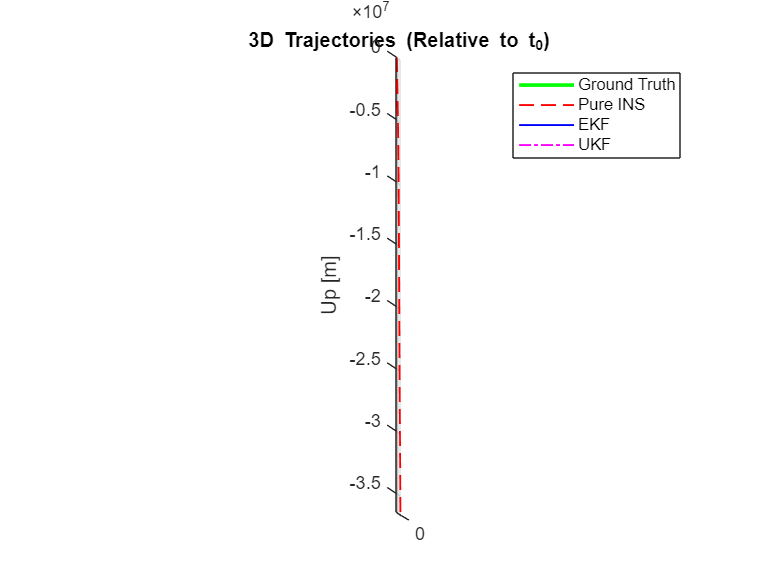

%% 7. Plot Trajectories & Compare with Ground Truth
figure('Name','3D Trajectory Comparison','NumberTitle','off');
plot3(gtPos_valid(:,1), gtPos_valid(:,2), gtPos_valid(:,3), 'g-', 'LineWidth', 2); hold on;
plot3(posINS_valid(:,1), posINS_valid(:,2), posINS_valid(:,3), 'r--', 'LineWidth', 1);
plot3(posEKF_valid(:,1), posEKF_valid(:,2), posEKF_valid(:,3), 'b-', 'LineWidth', 1);
plot3(posUKF_valid(:,1), posUKF_valid(:,2), posUKF_valid(:,3), 'm-.', 'LineWidth', 1);
legend('Ground Truth','Pure INS','EKF','UKF','Location','best');
xlabel('East [m]'); ylabel('North [m]'); zlabel('Up [m]');
title('3D Trajectories (Relative to t_0)');
grid on; axis equal;

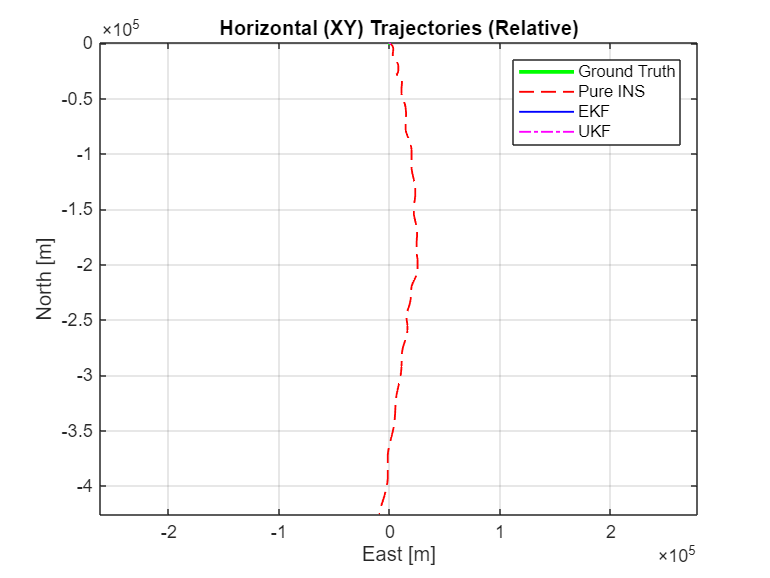


figure('Name','Horizontal (XY) Trajectories','NumberTitle','off');
plot(gtPos_valid(:,1), gtPos_valid(:,2), 'g-', 'LineWidth', 2); hold on;
plot(posINS_valid(:,1), posINS_valid(:,2), 'r--', 'LineWidth', 1);
plot(posEKF_valid(:,1), posEKF_valid(:,2), 'b-', 'LineWidth', 1);
plot(posUKF_valid(:,1), posUKF_valid(:,2), 'm-.', 'LineWidth', 1);
legend('Ground Truth','Pure INS','EKF','UKF','Location','best');
xlabel('East [m]'); ylabel('North [m]');
title('Horizontal (XY) Trajectories (Relative)');
axis equal; grid on;

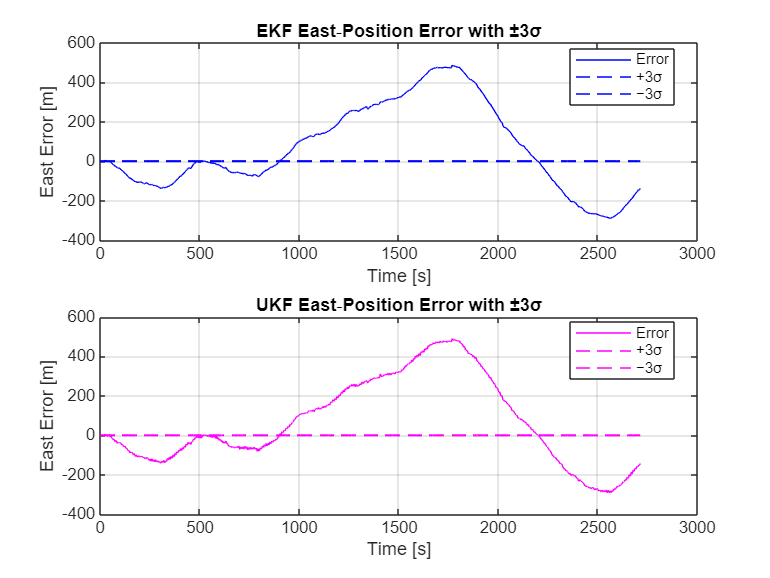

%% 8. Plot Estimation Errors & ±3σ Bounds (Fixed)
% ——————————————————————————————————————————————————————
% Compute East/North/Up errors for EKF & UKF against GT
errE_EKF = posEKF_valid(:,1) - gtPos_valid(:,1);
errN_EKF = posEKF_valid(:,2) - gtPos_valid(:,2);
errU_EKF = posEKF_valid(:,3) - gtPos_valid(:,3);

errE_UKF = posUKF_valid(:,1) - gtPos_valid(:,1);
errN_UKF = posUKF_valid(:,2) - gtPos_valid(:,2);
errU_UKF = posUKF_valid(:,3) - gtPos_valid(:,3);

% Extract ±3σ from covariances at valid indices
sigmaE_EKF = 3 * sqrt( squeeze(P_ekf(1,1, idxValidGT)) );  
sigmaN_EKF = 3 * sqrt( squeeze(P_ekf(2,2, idxValidGT)) );
sigmaU_EKF = 3 * sqrt( squeeze(P_ekf(3,3, idxValidGT)) );

sigmaE_UKF = 3 * sqrt( squeeze(P_ukf(1,1, idxValidGT)) );
sigmaN_UKF = 3 * sqrt( squeeze(P_ukf(2,2, idxValidGT)) );
sigmaU_UKF = 3 * sqrt( squeeze(P_ukf(3,3, idxValidGT)) );

% Time axis for valid segment, starting at zero
t_valid0 = t_valid - t_valid(1);

% --- East‐position error plot ---
figure('Name','East‐Position Error & ±3σ','NumberTitle','off');
subplot(2,1,1);
plot(t_valid0, errE_EKF, 'b-', t_valid0, sigmaE_EKF, 'b--', t_valid0, -sigmaE_EKF, 'b--');
xlabel('Time [s]'); ylabel('East Error [m]');
title('EKF East‐Position Error with ±3σ');
legend('Error','+3σ','−3σ','Location','best'); grid on;

subplot(2,1,2);
plot(t_valid0, errE_UKF, 'm-', t_valid0, sigmaE_UKF, 'm--', t_valid0, -sigmaE_UKF, 'm--');
xlabel('Time [s]'); ylabel('East Error [m]');
title('UKF East‐Position Error with ±3σ');
legend('Error','+3σ','−3σ','Location','best'); grid on;

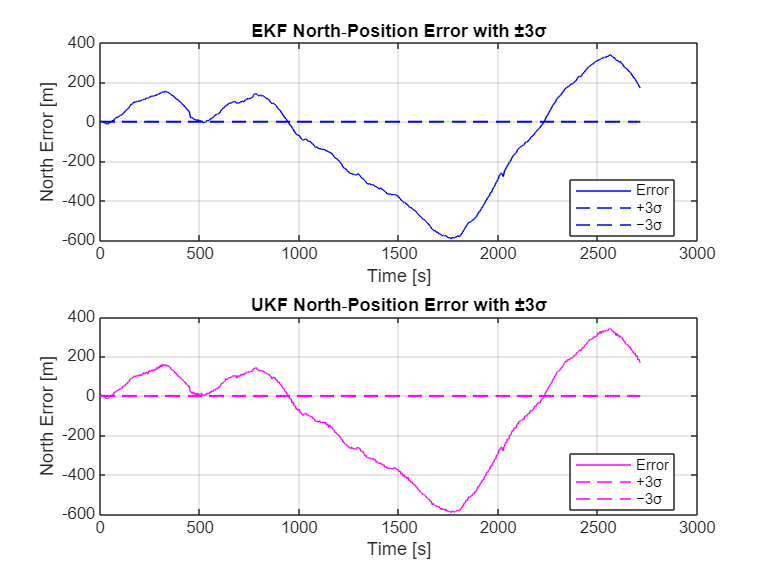


% --- North‐position error plot ---
figure('Name','North‐Position Error & ±3σ','NumberTitle','off');
subplot(2,1,1);
plot(t_valid0, errN_EKF, 'b-', t_valid0, sigmaN_EKF, 'b--', t_valid0, -sigmaN_EKF, 'b--');
xlabel('Time [s]'); ylabel('North Error [m]');
title('EKF North‐Position Error with ±3σ');
legend('Error','+3σ','−3σ','Location','best'); grid on;

subplot(2,1,2);
plot(t_valid0, errN_UKF, 'm-', t_valid0, sigmaN_UKF, 'm--', t_valid0, -sigmaN_UKF, 'm--');
xlabel('Time [s]'); ylabel('North Error [m]');
title('UKF North‐Position Error with ±3σ');
legend('Error','+3σ','−3σ','Location','best'); grid on;

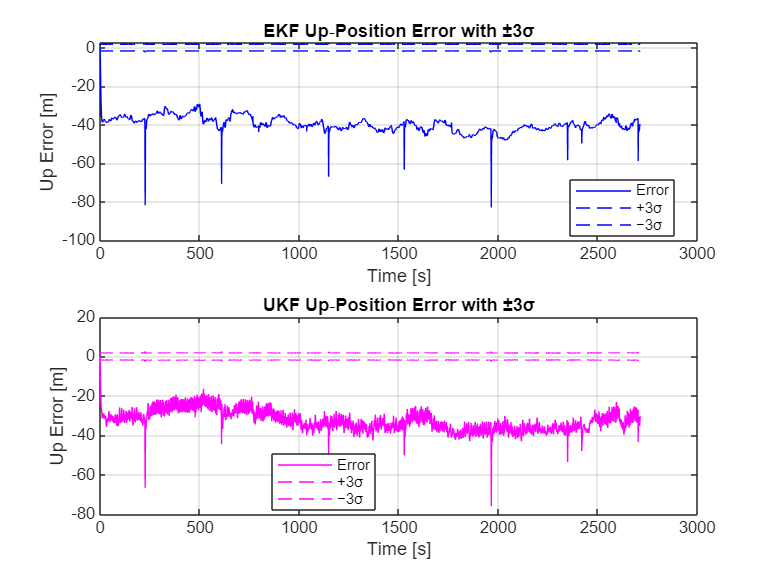


% --- Up‐position error plot ---
figure('Name','Up‐Position Error & ±3σ','NumberTitle','off');
subplot(2,1,1);
plot(t_valid0, errU_EKF, 'b-', t_valid0, sigmaU_EKF, 'b--', t_valid0, -sigmaU_EKF, 'b--');
xlabel('Time [s]'); ylabel('Up Error [m]');
title('EKF Up‐Position Error with ±3σ');
legend('Error','+3σ','−3σ','Location','best'); grid on;

subplot(2,1,2);
plot(t_valid0, errU_UKF, 'm-', t_valid0, sigmaU_UKF, 'm--', t_valid0, -sigmaU_UKF, 'm--');
xlabel('Time [s]'); ylabel('Up Error [m]');
title('UKF Up‐Position Error with ±3σ');
legend('Error','+3σ','−3σ','Location','best'); grid on;

%% 9. Bonus: Loosely‐ vs Tightly‐Coupled Integration Discussion
% In this script, we implemented a *loosely‐coupled* EKF and UKF:
%   - The filter state includes INS position, velocity, and attitude.
%   - GPS measurements (position fix) and barometric altitude are fed as
%     direct measurements of the INS position states.
%
% A *tightly‐coupled* integration would instead use raw GPS observations
% (pseudoranges and range rates) as filter inputs, augmenting the state to
% include satellite clock biases, receiver clock bias, and possibly other
% terms. The measurement model would compute predicted pseudoranges from the
% INS‐estimated receiver position & satellite ephemerides, then compare
% against actual pseudorange measurements. In urban environments with fewer
% visible satellites, tightly‐coupled allows a position solution with as
% few as 3 satellites, whereas loosely‐coupled requires ≥4 satellites for
% a full 3D fix.
%
% Pseudocode for a tightly‐coupled UKF (conceptual outline):
%
%   %--- State x = [p; v; q; clock_bias; clock_drift; sat_clock_biases...] ---
%   %--- Measurements z = [pseudorange_1; …; pseudorange_m] ---
%   for k = 1:N-1
%     % (a) UKF Prediction: propagate INS portion (p,v,q) as above;
%     %     propagate clock bias/drift with simple random‐walk models.
%     % (b) Form sigma points around x_k, propagate each through INS + clock model.
%     % (c) Predict pseudoranges h_i(x) = ||p_sat_i(k) - p_ukf|| + c*(clock_bias) + ...
%     % (d) Compute measurement covariance using satellite geometry matrix H.
%     % (e) UKF Update: incorporate raw pseudoranges, update x, P.
%   end
%
% Implementing a fully‐tightly‐coupled solution requires raw GPS ephemerides
% (satellite positions as a function of time) and pseudorange logs. The
% Zurich MAV dataset only provides processed GPS fixes, so we used the
% loosely‐coupled approach here. If raw GPS logs become available, one can
% extend this script along the lines shown above.

%% Local Functions (Quaternion Math)
% The following local functions implement quaternion multiplication,
% normalization, and conversion to rotation matrix, so that this live
% script is self-contained and does not require any specialized MATLAB
% toolboxes.

%% Local Functions for Quaternion Math
function q_out = quatmultiply(q1, q2)
    % Multiply two quaternions (scalar-first convention)
    % q1, q2: 1×4 [qw, qx, qy, qz]
    a1 = q1(1); b1 = q1(2); c1 = q1(3); d1 = q1(4);
    a2 = q2(1); b2 = q2(2); c2 = q2(3); d2 = q2(4);
    q_out = [ ...
        a1*a2 - b1*b2 - c1*c2 - d1*d2, ...
        a1*b2 + b1*a2 + c1*d2 - d1*c2, ...
        a1*c2 - b1*d2 + c1*a2 + d1*b2, ...
        a1*d2 + b1*c2 - c1*b2 + d1*a2 ...
    ];
end

function C = quat2rotm(q)
    % Convert a quaternion (1×4) to a 3×3 rotation matrix
    % Quaternion in scalar-first form: [qw, qx, qy, qz]
    qw = q(1); qx = q(2); qy = q(3); qz = q(4);
    C = [ ...
      1 - 2*qy^2 - 2*qz^2,    2*qx*qy - 2*qz*qw,    2*qx*qz + 2*qy*qw; ...
      2*qx*qy + 2*qz*qw,      1 - 2*qx^2 - 2*qz^2,  2*qy*qz - 2*qx*qw; ...
      2*qx*qz - 2*qy*qw,      2*qy*qz + 2*qx*qw,    1 - 2*qx^2 - 2*qy^2 ...
    ];
end